# Thermo 2019 chapter 5 part B 

R=8.31; Cv=20.8; Cp=29.1; % diatomic
T298=298; Po=1e5;

## **Exo 5.5 : Oreo biscuits**

Sucrose, $\mathrm{C_{12}H_{22}O_{11(s)}$ (*saccharose *in French) is a suggar extracted mainly from sugarcane and sugar beet, widely used for human food. 

**1. **Write the equation of the standard formation of solid sucrose. The value of the 298 K standard molar enthalpy associated to this reaction is $-2218.3\,\mathrm{kJmol^{-1}}$.

    $\mathrm{12C+11H_2+\frac{11}{2}O_2\rightarrow C_{12}H_{22}O_{11}}$    (we start from the simple elements in their reference state)

**2. **Write the reaction of the combustion of solid sucrose in gaseous $\mathrm{O_2}$ forming $\mathrm{CO_2}$ and liquid water. The stoichiometric coefficient of sucrose will be set to 1. 

    
$$\mathrm{ C_{12}H_{22}O_{11} + 12O_2\rightarrow 12CO_2+11H_2O_l}$$
        

(If the stoichiometric coefficient is not set to 1, then do not forget to devide by this number to express the mola combustion reaction of one mole of sucrose)

**3.** Calculate the standard enthalpy of this reaction at 25°C. Is this reaction endo- or exothermal ? 

    
$$\Delta_r\bar H_{298}=12\Delta_f\bar H_{(CO_2)}+11\Delta_f\bar H_{(H_2O)}-\Delta_f\bar H_{(C_{12}H_{22}O_{11})}$$


DfH_C12H22O11=-2218.3; DfH_CO2=-393.5; DfH_H2Ol=-285.8;
DrH_298=12*DfH_CO2+11*DfH_H2Ol-DfH_C12H22O11; fprintf('DrH_298 = %1.1f MJ/mol',DrH_298/1e3) % in kJ/mol

DrH_298 = -5.6 MJ/mol

 the value is negative, therefore exothermal.

**4.** NOT TO BE DONE THIS YEAR Calculate the standard enthalpy of this reaction at 37°C (body temperature of humans). Comment the difference with the 25°C value. 

    We apply the Kirchoff law (direct application of first law on state variables) :

    298 K : $\mathrm{ C_{12}H_{22}O_{11} + 12O_2\rightarrow 12CO_2+11H_2O_l}$

    310 K : $\mathrm{ C_{12}H_{22}O_{11} + 12O_2\rightarrow 12CO_2+11H_2O_l}$

    
$$\Delta_r\bar H_{310}=\Delta_r\bar H_{298}+\int_{298}^{310}\big(12\bar C_{p\,(CO_2)}+11\bar C_{p\,(H_2Ol)}\big)dT-\int_{298}^{310}\big(12\bar C_{p\,(O_2)}+\bar C_{p\,(C_{12}H_{22}O_{11})}\big)dT$$


Cp_C12H22O11=489.7; Cp_O2=29.4; Cp_CO2=45; Cp_H2Ol=75.3;
DrH_310=DrH_298+(12*Cp_CO2+11*Cp_H2Ol-12*Cp_O2-Cp_C12H22O11)*(310-298)*1e-3; % in kJ/mol
fprintf('DrH_310 = %1.1f MJ/mol',DrH_310/1e3)

DrH_310 = -5.6 MJ/mol


err=(DrH_310-DrH_298)/DrH_298*100; fprintf('err = %1.1f %%',err) % in %

err = -0.1 %

  therefore negligeable

This combustion reaction of sucrose from the sweet products is daily operating in our body and supplies a fraction of our necessary energy. The French *ANC, ****Apports Nutritionnels Conseillés*** equivalent of the RDA, Recommended Dietary Allowances, suggest a daily quantity of sucrose of 5 to 10% of the Total Energy Expenditure (TEE) in a 24-hour period. 

**5.** How many Oréo biscuits can you eat per day to respect this nutrition advice ?

*Data :*

Total Energy Expenditure (TEE) : 8360 kJ

Sucrose content of a Oréo biscuit : 5 g

Molar mass of sucrose : $M_{(C_{12}H_{22}O_{11(s)})} = 342\,\mathrm{gmol^{-1}$

   say $S_{or}=5\,\mathrm g$, $\rho=0.10$ the percentage of the expenditure, then the number of Oréo : $nb=\frac{\rho \times TEE\times M_{C_{12}H_{22}O_{11}}}{-\Delta_r\bar H_{310}\times S_{or}}$

rho=0.1; S_or=5e-3; M_C12H22O11=342e-3; TEE=8360;
nb=-rho*TEE*M_C12H22O11/DrH_310/S_or; fprintf('nb = %1.0f biscuits',nb)

nb = 10 biscuits

## Exo 5.6 : Effect of temperature

Above a given temperature $T_{lim}$, gaseous heptane $\mathrm{C_7H_{16(g)}}$ spontaneously dissolves into gaseous toluene $\mathrm{C_7H_{8(g)}}$ and into gaseous dihydrogen. This is called reforming of heptane.

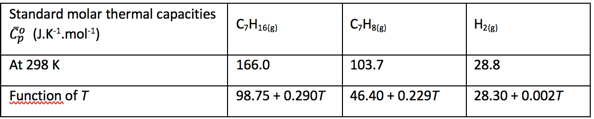

**1.** Write the equation of this reaction using the smallest stoichiometric coefficients.

    
$$\mathrm{C_7H_{16(g)}\rightarrow C_7H_{8(g)}+4H_{2(g)}}$$


**2. **At 298 K the standard enthalpy of that reaction is equal to $+237.8\,\mathrm{kJmol^{-1}}$. In industry this reaction is processed at 750 K. Calculate $\Delta_r\bar H_{750}^o$.                              :

Using the thermal capacities at 298 K assuming them independent of the temperature.

    
$$\Delta_r\bar H_{298}=+237.8\,\mathrm{kJmol^{-1}}$$


    
$$\Delta_r\bar H_{750}=\Delta_r\bar H_{298}+\int_{298}^{750}\big(\bar C_{p\,(C_7H_8)}+4\bar C_{p\,(H_2)}-\bar C_{p\,(C_7H_{16})}\big)dT$$


DrH_298=237.8; Cp_C7H16=165.2; Cp_C7H8=103.7; Cp_H2=28.8;
DrH_750=DrH_298+(Cp_C7H8+4*Cp_H2-Cp_C7H16)*(750-298)*1e-3; % in kJ/mol
fprintf('DrH_750 = %1.1f kJ/mol',DrH_750) 

DrH_750 = 262.1 kJ/mol

**3. **Considering the $\bar C_p^o$ values temperature independent, calculate the molar entropies of this reaction at 298 K then at 750 K.

    
$$\Delta_r\bar S_{298}=\bar S_{(C_7H_8)}+4\bar S_{(H_2)}-\bar S_{(C_7H_{16})}$$


    
$$\Delta_r\bar S_{750}=\Delta_r\bar S_{298}+\int_{298}^{750}\Big(\frac{\bar C_{p\,(C_7H_8)}}{T}+4\frac{\bar C_{p\,(H_2)}}{T}-\frac{\bar C_{p\,(C_7H_{16})}}{T}\Big)dT$$
  
$$\iff \Delta_r\bar S_{750}=\Delta_r\bar S_{298}+\big(\bar C_{p\,(C_7H_8)}+4\bar C_{p\,(H_2)}-\bar C_{p\,(C_7H_{16})}\big)\ln{\frac{750}{298}}$$


S_C7H8g=319.7; S_C7H16g=424.9; S_H2=130.7;
DrS_298=S_C7H8g+4*S_H2-S_C7H16g; fprintf('DrD_298 = %1.0f J/mol/K',DrS_298)   % in J/K/mol

DrD_298 = 418 J/mol/K

DrS_750=DrS_298+(Cp_C7H8+4*Cp_H2-Cp_C7H16)*log(750/298); fprintf('DrS_750 = %1.0f J/mol/K',DrS_750) % in J/K/mol

DrS_750 = 467 J/mol/K

**4.** Calculate $\Delta G^0$ at both temperature and comment

assuming coefficient temp independant :

$\Delta_r\bar G_{298}=\Delta_r\bar H_{298}-T_{298}\cdot\Delta_r\bar S_{298}$ and $\Delta_r\bar G_{750}=\Delta_r\bar H_{750}-T_{750}\cdot\Delta_r\bar S_{750}$

DrG_298=DrH_298-298*DrS_298*1e-3; fprintf('DrG_298 = %1.0f kJ/mol',DrG_298)

DrG_298 = 113 kJ/mol

DrG_750=DrH_750-750*DrS_750*1e-3; fprintf('DrG_750 = %1.0f kJ/mol',DrG_750)

DrG_750 = -88 kJ/mol

The reaction enthalpy values are $\Delta_r \bar G_{298}^0=113\,\mathrm{kJ\cdot mol^{-1}}$ and $\Delta_r \bar G_{750}^0=-75.3\,\mathrm{kJ\cdot mol^{-1}}$. Since the reactions are uner isobaric and monothermal conditions, the enthalpy is a potential function, therefore shows that the reaction is not possible at 298K and spontaneous at 750K. However, this calculation has been conducted assuming the $C_p$ temperature independant, and is not precise enough to determine the critical temperature above which the reaction is possible.

**5. **Using the expressions of the thermal capacities as function of the temperature *T*.

    The equation is the same but the coefficients differents

fCp_C7H16=@(T) 98.75+0.29*T;  % f in front to show the temperature function
fCp_C7H8=@(T) 46.4+0.229*T;
fCp_H2=@(T) 28.3+0.002*T;
INT_Cp=@(T) fCp_C7H8(T)+4*fCp_H2(T)-fCp_C7H16(T);
DrH_750_b=DrH_298+integral(INT_Cp,298,750)*1e-3 ; fprintf('DrH_750_b = %1.0f J/mol/K',DrH_750_b) %in kJ/mol

DrH_750_b = 253 J/mol/K

% in addition
% to take into account the Cp(T) : numerical integration
INT_Cp=@(T) (fCp_C7H8(T)+4*fCp_H2(T)-fCp_C7H16(T))./T;
DrS_750=DrS_298+integral(INT_Cp,298,750); fprintf('DrS_750 = %1.0f J/mol/K',DrS_750)    % in J/K/mol

DrS_750 = 450 J/mol/K

## Exo 5.7 : Storing chemical energy

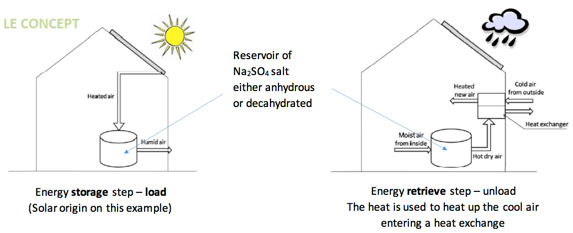

The direct determination of standard enthalpy of hydration of the anhydrous salt sodium sulfate $\mathrm{Na_2SO_{4 (s)}}$ to its hydrated form decahydrate sodium sulfate $\mathrm{Na_2SO_4,10H_2O_{(s)}}$, at ambient temperature (written $\Delta_{hydr}\bar H_T^o$) by a calorimetry experiment is not possible. It is however possible to do it indirectly by measuring the dissolution enthalpy in the solvent $\mathrm{H_2O}$ of $\mathrm{Na_2SO_{4(s)}}$ anhydrous on the first hand (written $\Delta_{dissol1}\bar H_T^o$ ), and the dissolution enthalpy of $\mathrm{Na_2SO_4,10H_2O_{(s)}}$ on the other hand (written $\Delta_{dissol2}\bar H_T^o$ ). 

**1. **Write the chemical reaction associated to the hydration of one mole of  anhydrous $\mathrm{Na_2SO_{4 (s)}}$.

    $\mathrm{Na_2SO_{4 (s)}+10 H_2O\rightarrow Na_2SO_4,10H_2O}$   ($\Delta_{hydr}\bar H_T^o$)

**2.** Write and balance both considered dissolution reactions. 

    $\mathrm{Na_2SO_{4 (s)}\rightarrow 2Na^++SO_4}$       ($\Delta_{dissol1}\bar H_T^o$)

    $\mathrm{Na_2SO_4,10H_2O_{(s)}\rightarrow 2Na^++SO_4+10 H_2O}$   ($\Delta_{dissol2}\bar H_T^o$)

**3.** Build a thermodynamics cycle including the dissolution reactions of anhydrous $\mathrm{Na_2SO_{4 (s)}}$ and of $\mathrm{Na_2SO_4,10H_2O_{(s)}}$ and the hydration reaction of anhydrous $\mathrm{Na_2SO_{4 (s)}}$.

    reaction 1 can be achieved by subtracting rection 3 to reaction 2

**4.** Deduce a relation between $\Delta_{hydr}\bar H_T^o$, $\Delta_{dissol1}\bar H_T^o$ and $\Delta_{dissol2}\bar H_T^o$, specifying the property of the function $H$you apply.

    
$$\Delta_{hydr}\bar H_T^o=\Delta_{dissol1}\bar H_T^o-\Delta_{dissol2}\bar H_T^o$$
       

    This can be done because $H$ is a state function

From an experiment we measure at room temperature $\Delta_{dissol1}\bar H_T^o=-2\pm 5\,\mathrm{kJmol^{-1}}$ and $\Delta_{dissol2}\bar H_T^o=78\pm 5\,\mathrm{kJmol^{-1}}$ . 

**5.** Calculate $\Delta_{hydr}\bar H_T^o$, the standard enthalpy of hydration of anhydrous salt $\mathrm{Na_2SO_{4 (s)}}$ to its hydrated form $\mathrm{Na_2SO_4,10H_2O_{(s)}}$, at room temperature. Is this reaction endo- or exothermal ? 

Ddis1H=-2; Ddis2H=78;
DhydH=Ddis1H-Ddis2H; fprintf('DhydH = %1.0f kJ/mol',DhydH)  % in kJ/mol

DhydH = -80 kJ/mol

 therefore exothermal.

This hydration reaction of the salt can be used to thermochemical storage of energy. The idea is explained on the schematic drawing below. 

**6.** Does the hydration reaction of the anhydrous salt into a decahydrate sodium sulfate salt take place during the storage or the retrieve step ? Precisely identify the chemical reactions that take place in each step. 

    hydratation reaction since exothermal : energy retrieve step

**7. **Calculate the stored energy if the reservoir contains 1 kg of salt. 

    $m=1\,\mathrm{kg}$, $M_{(Na_2SO_4)}=100.2\,\mathrm{gmol^{-1}}$

    $E=-\frac{m\times \Delta_{hydr}\bar H_T^o}{M_{(Na_2SO_4)}}$   (energy stored per kg of salt)

m=1; M_Na2SO4=(22*2+32+16*4)*1e-3;
E=-m*DhydH/M_Na2SO4; fprintf('E = %1.0f KJ/kg',E) %in kJ/kg

E = 571 KJ/kg

**8.** Calculate the required mass of salt to heat up to 20°C the air contained in a $50\,\mathrm{m^3}$ room, assuming that the initial temperature was 10°C.

We consider a thermal capacity of air equal to $1.256\,\mathrm{ kJm^{-3}K^{-1}}$.

    $C_{p,air}=1.256\,\mathrm{ kJm^{-3}K^{-1}}$, $V_r=50\,\mathrm{m^3}$

    
$$m_{salt}=\frac{V_rC_{p,(air)}(20-10)}{E}$$
 

Cp_vair=1.256; Vr=50; DT=10;
m_salt=Vr*Cp_vair*DT/E; fprintf('m_salt = %1.2f kg',m_salt) % in kg

m_salt = 1.10 kg

  .

## Exo 5.8 : Condensation burner

Before buying a water heater to produce hot water in our home, we want to use our thermodynamics 1st year expertise to compare the different solutions. 

*A water heater being working continuously, in this exercise all quantities will be calculated per unit time (= per second) and will be written for instance *$\dot n$ *for the number of moles per second, or *$\dot Q$  *for the heat transfer per second**.*

The burner of a water heater is fed at constant temperature and pressure ($P_0 =1\,\mathrm{bar}$, $T_{g,i}=20^\circ\mathrm{C}$) by $\dot n_{C_3H_8,i}= 0.01\,\mathrm{mol.s^{-1}$ of gaseous propane ($\mathrm{C_3H_8}$)and dry air. The air introduced allows to have a quatity of dioxygen which is 1.4 times the stoichiometric proportion. The combustion of propane is total and leads to the formation of gaseous carbon dioxide and water. The gases coming out of the burner are evacuated to the chimney after having heated liquid water entering at $T_{w,I}= 15^\circ\mathrm{C}$ and leaving at $T_{w,o}= 45^\circ\mathrm{C}$. We write $\dot m_{water}$ the mass flow (in g/s) of liquid water. The whole setup works at a constant pressure of 1.0 bar. 

**1st study** : 

The combustion gases (products + excess reactants) are evacuated into the chimney at temperature $T_{g,o} = 105^\circ\mathrm{C}$ ; in these conditions the water formed by the combustion is completely in the gaseous state. 

**1. **Complete the sketch of the setup on the result sheet, specifying temperatures. 

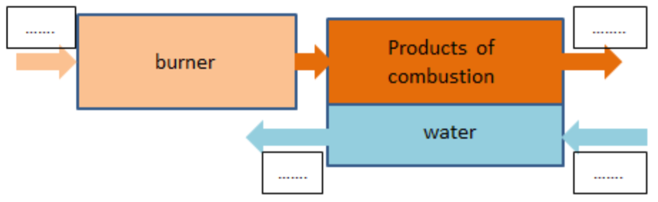

gas input : $T_{gi}=20\mathrm{°C}$, gas product of combustion $T_{go}=105\mathrm{°C}$, water imput : $T_{wi}=15\mathrm{°C}$, water output : $T_{wo}=45\mathrm{°C}$.

**2. **Write the combustion reaction of propane, water formed as vapour (complete reaction). 

    
$$\mathrm{C_3H_8+5O_2\rightarrow 3 CO_2 +4 H_2O_ {(g)}}$$


    1.4 the stoichiometry of dry air means $1\times O_2$ for the reaction and $0.4\times O_2$ remaining unburnt, which leads to :

                   
$$\mathrm{2O_2\rightarrow 2O_2}$$


                    
$$\mathrm{28N_2\rightarrow 28N_2}$$


**3.** Complete the ICE table indicating the input, intermediate and output matter quantities (per second) on the result sheet (you’ll call $\dot\xi$                            the extend of reaction per second).

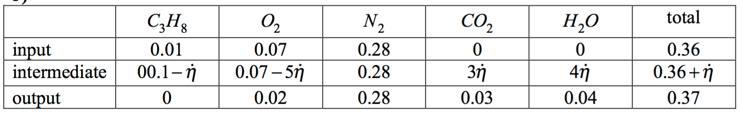

**4. **Calculate the standard molar enthalpy of this reaction at 298 K ($\Delta_r\bar H_{298}^o$). 

        
$$\Delta_r\bar H_{298}=4\Delta_f\bar H_{298,(H_2O\,g)}+3\Delta_f\bar H_{298,(CO_2\,g)}-\Delta_f\bar H_{298,(C_3H_8)}$$


DfH_C3H8=-103.8; DfH_H2Og=-241.8;
DrH=4*DfH_H2Og+3*DfH_CO2-DfH_C3H8; fprintf('DrH = %1.0f kJ/mol',DrH)

DrH = -2044 kJ/mol

**c) **From a calculation show the standard molar enthalpy of this combustion reaction at 298  K is almost equal to that at 293 K. 

    
$$\Delta_r\bar H_{293}=\Delta_r\bar H_{298}+\int_{298}^{293}(4\bar C_{p,(H_2Og)}+3\bar C_{p,(CO2)}-\bar C_{p,(C_3H_8)}-5\bar C_{p,(O_2)})dT$$


Cp_H2Og=33.6; Cp_C3H8=73.6; 
DrH_293=DrH+(4*Cp_H2Og+3*Cp_CO2-Cp_C3H8-5*Cp_O2)*(293-298)*1e-3

DrH_293 = -2.0441e+03

    the standard molar enthalpy of this reaction at 293K is $\Delta_r\bar H_{293}=-2044.1\,\mathrm{kJ\cdot mol^{-1}}$, therefore wery close.

**d)** From a calculation show that this reaction is complete at 298 K. 

**5. a) **Express the power $\dot Q_r$ released by the reaction in these conditions of supply of the heater. 

    call $\dot n$ the input gas flow (in mol/s) and call $\dot m_w$ the water flow.

    The heat rate produced by the reaction is $\dot Q_{r}=\dot n\cdot \Delta_r\bar H$

**   b) **Using questions 1 and 3, express the power $\dot Q_w$ necessary to heat up liquid water and the power $\dot Q_g$necessary to heat up the combustion gases from $T_{g,i}$  to $T_{g,o}$.   

    The heat rate to heat up the gases is $\dot Q_g=\dot n(2\bar C_{p,(O_2)}+28\bar C_{p,(N_2)}+3\bar C_{p,(CO_2)}+4\bar C_{p,(H_2Og)})(T_{go}-T_{gi})$

    The heat received by the water is $\dot Q_w=\dot m_w c_w(T_{wo}-T_{wi})$ where $c_w$ is the specific capacity of water.

**6. **Considering there is no thermal loss (adiabatic operation), establish a relation between $\dot Q_r$, $\dot Q_w$   and $\dot Q_g$.

Energy balance : $\dot Q_w+\dot Q_r+\dot Q_g=0$ $\iff \dot m_w=-\frac{\dot n\cdot \Delta_r\bar H+\dot n(2\bar C_{p,(O_2)}+28\bar C_{p,(N_2)}+3\bar C_{p,(CO_2)}+4\bar C_{p,(H_2Og)})(T_{go}-T_{gi})}{c_w(T_{wo}-T_{wi})}$

n=0.01; Cp_N2=29.1; Cp_O2=29.1; Tgi=273+25; Tgo=273+105; cp_w=Cp_H2Ol/(18e-3); Twi=273+15; Two=273+45;
Qr=n*DrH; fprintf('Qr = %1.1f kJ/s',Qr) % in kJ/s

Qr = -20.4 kJ/s

Qg=n*(2*Cp_O2+28*Cp_N2+3*Cp_CO2+4*Cp_H2Og)*(Tgo-Tgi)*1e-3; fprintf('Qg = %1.2f kJ/s',Qg) % in kJ/s

Qg = 0.91 kJ/s

**7.** Deduce the mass flow rate $\dot m_w$ of hot water (quantity of water heated per second in the exchanger). 

m_w=-(Qr+Qg)/(cp_w*(Two-Twi))*1e3; fprintf('m_w = %1.0f g/s',m_w*1e3)   % in kg/s

m_w = 156 g/s

**8.** What mass of propane must be used to give the water a total energy of 100 kWh to water.  What is the corresponding cost in euros ?

    
$$Q_{100}=100\,\mathrm{kWh}=3.6\times 10^{5}\,\mathrm{kJ}$$


    For gas $\dot n\cdot \Delta t$, heat quantity : $\dot Q_w\cdot \Delta t$, simple proportion :   $\frac{n_{g,100}}{\dot n}=\frac{Q_{100}}{\dot Q_w}$ $\iff m_{g,100}=\dot n \frac{Q_{100}}{\dot Q_w}M_{C_3H_8}$

Q100=3.6e5; M_C3H8=3*12+8; Qw=m_w*cp_w*(Two-Twi);
m_g100=n*Q100/Qw*M_C3H8; fprintf('m_g100 = %1.1f kg',m_g100)  % in kg

m_g100 = 8.1 kg

mcost= 1.7; Cost= m_g100*mcost; fprintf('Cost = %1.1f €',Cost)

Cost = 13.8 €

**2nd study** : the gas of the burner are now evacuated at 45°C.

**9. **At 45°C, is the water formed during the combustion still in the vapour state ? Justify the answer from the ICE table of the matter at the output of the burner established in question 3 and from the data of the question. 

From the ICE table one can calculate the partial pressure of H2O : $P_{H_2O}=P_o\frac{n_{H_2O}}{n_{tot}}$ and compare to $P_{VS}$

n_H2O=0.04; n_tot=0.37; Po=1e5; Pvs=9583;
P_H2O=Po*n_H2O/n_tot;  fprintf('P_H2O = %1.2e Pa',P_H2O)

P_H2O = 1.08e+04 Pa

so $P_{H_2O}>P_{VS}$, so the water is partially condensed

**10.** Calculate the water flow rate at the burner output, then the liquid water flow rate. 

    $n_{w,g}=\frac{P_{VS}}{P_{H_2O}}n_{H_2O}$  and $n_{w,l}=n_{H_2O}-n_{w,g}$

n_wg=Pvs/P_H2O*n_H2O; fprintf('n_wg = %1.3f mol/s',n_wg)

n_wg = 0.035 mol/s

n_wl=n_H2O-n_wg; fprintf('n_wl = %1.3f mol/s',n_wl)

n_wl = 0.005 mol/s

**11.** For these new working conditions, calculate the power received by the liquid water, then the cost of the propane used to supply 100 kWh to water to heat up. Conclusion.

let's call $\Delta_rH_l$ the heat of the reaction leading to liquid water : $\Delta_rH_l=\Delta_rH-4\Delta_{vap}H$


$$Q_r\prime = \frac{n_{w,g}}{n_{H_2O}}\Delta_rH+\frac{n_{w,l}}{n_{H_2O}}\Delta_rH_l$$


DvapH_w=44e3; % vaporisation of water in kJ/mol va
DrH_l=DrH-4*DvapH_w;
Qr=n*((n_wg/n_H2O)*DrH+(n_wl/n_H2O)*DrH_l)

Qr = -220.3266

Qg=n*(2*Cp_O2+28*Cp_N2+3*Cp_CO2+4*(n_wg/n_H2O)*Cp_H2Og)*(Tgo-Tgi)*1e-3;
m_w=-(Qr+Qg)/(cp_w*(Two-Twi))*1e3; fprintf('m_w = %1.0f g/s',m_w*1e3)   % in kg/s

m_w = 1748 g/s

Qw=m_w*cp_w*(Two-Twi);
m_g100=n*Q100/Qw*M_C3H8; fprintf('m_g100 = %1.1f kg',m_g100)  % in kg

m_g100 = 0.7 kg

mcost= 1.7; Cost= m_g100*mcost; fprintf('Cost = %1.1f €',Cost)

Cost = 1.2 €

**12.** Show that reducing the gas temperature and condensing the highest possible quantity of water allows to reduce the cost. What is the effect of a reduction of the quantity of air injected in the burner ?